# Obstacle detection from stereo ground plane homography.

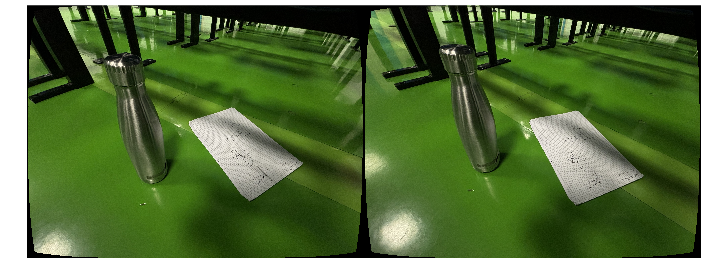

close all;

figuresOn = true;

imageFolder = 'images/ground';

imds = imageDatastore(imageFolder);
phoneCamera = load('cameraParams/iPhone_15_ultrawide_12mp.mat');
cameraParams = phoneCamera.cameraParams;

% Load the images.
images = cell(1, 2);
for i = 1:2
    images{i} = undistortImage(readimage(imds, i), cameraParams);
end

% Plot.
if figuresOn
    figure("Name", "Source images");
    imshowpair(images{1}, images{2}, 'montage');
end

## Load the homography.

load(imageFolder + "/homography.mat");

## Apply the homography to the first image.

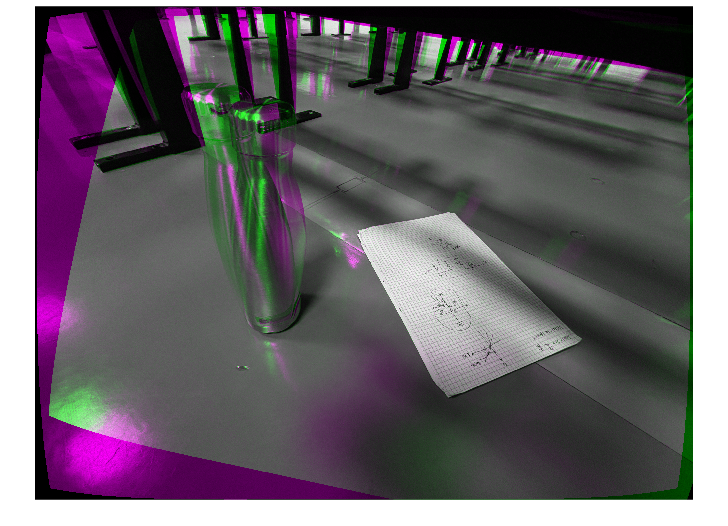

i1hom = imwarp(images{1}, H, 'OutputView', imref2d(size(images{2})));

if figuresOn
    figure("Name", "Homography");
    imshowpair(i1hom, images{2});
end

## Show difference.

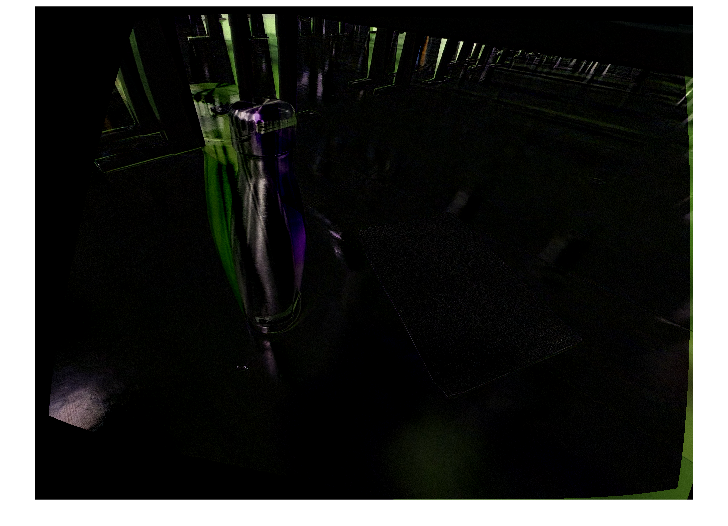

diff = i1hom - images{2};

if figuresOn
    figure("Name", "Difference");
    imshow(diff);
end

## Undistort a white image in order to create a mask.

white = true(size(images{1}, [1, 2]));
white = undistortImage(white, cameraParams);

mask1 = imwarp(white, H, 'OutputView', imref2d(size(images{2})));
mask2 = white;

completeMask = mask1 & mask2;

## Apply the mask to the difference.

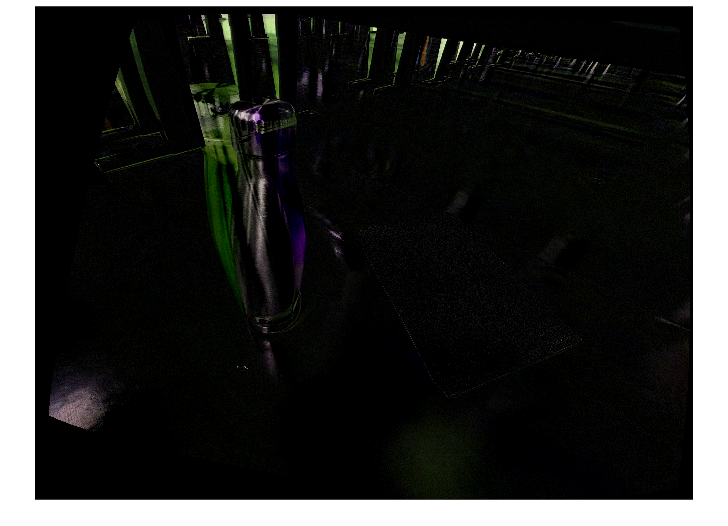

diffMasked = zeros(size(diff), "like", diff);
for i = 1:3
    diffMasked(:, :, i) = diff(:, :, i) .* uint8(completeMask);
end

if figuresOn
    figure("Name", "Masked difference");
    imshow(diffMasked);
end

## Threshold the difference.

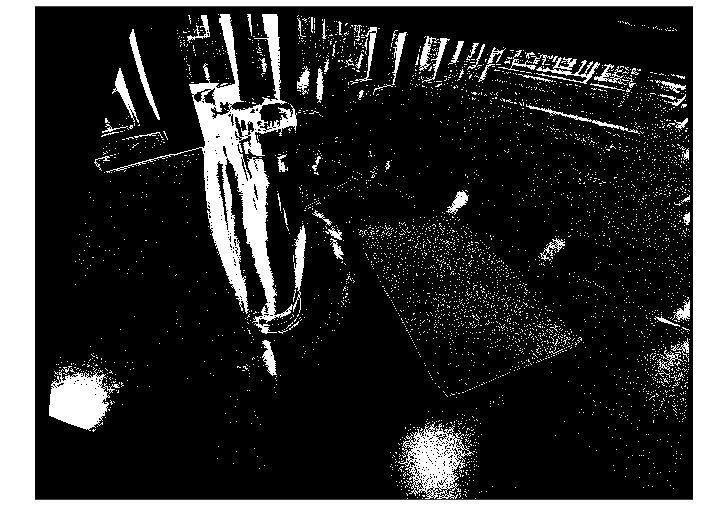

diffTh = im2gray(im2double(diffMasked));
diffTh = diffTh > 0.05;

if figuresOn
    figure("Name", "Thresholded difference");
    imshow(diffTh);
end

## Remove blobs under a certain thickness.

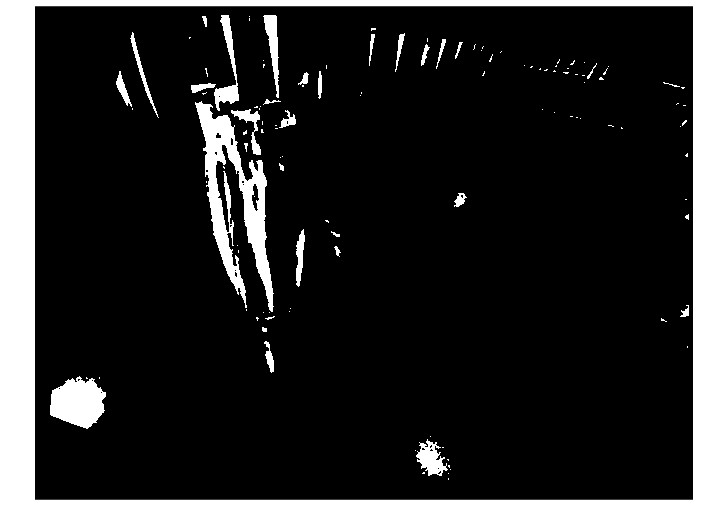

% Blur the image.
diffTh = imgaussfilt(double(diffTh), 5);

% Threshold again.
diffTh = diffTh > 0.9;

if figuresOn
    figure("Name", "Thresholded difference after blurring and re-thresholding");
    imshow(diffTh);
end

## Remove blobs under a certain size (percentile).

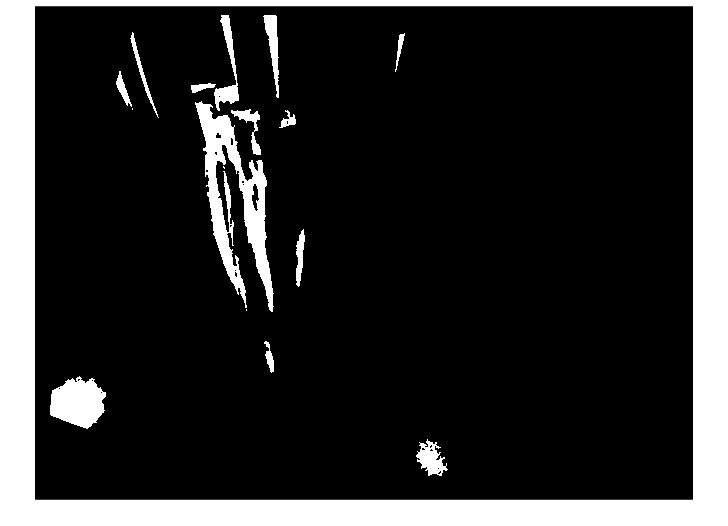

% Get the blob areas.
blobAreas = regionprops(diffTh, 'Area');
blobAreas = [blobAreas.Area];

% Get the percentile.
minArea = prctile(blobAreas, 90);

% Remove blobs under the threshold.
diffTh = bwareaopen(diffTh, round(minArea));

if figuresOn
    figure("Name", "Thresholded difference with small blobs removed");
    imshow(diffTh);
end

## Dilate (and erode?).

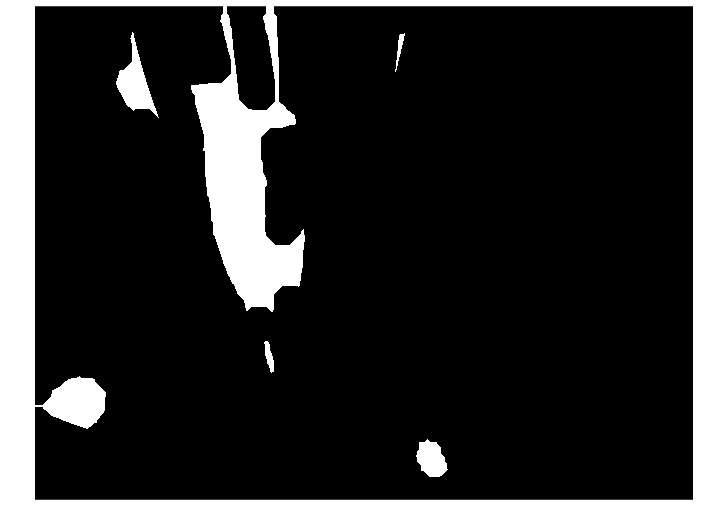

se = strel('disk', 100);
diffTh = imdilate(diffTh, se);
diffTh = imerode(diffTh, se);

if figuresOn
    figure("Name", "Thresholded difference with dilation");
    imshow(diffTh);
end

## Find the nearest white pixel in each column.

firstWhite = zeros(1, size(diffTh, 2));
for i = 1:size(diffTh, 2)
    column = diffTh(:, i);
    whiteidx = find(column, 1, "last");

    if ~isempty(whiteidx)
        firstWhite(i) = whiteidx;
    else
        firstWhite(i) = 0;
    end
end

## Filter spikes.

firstWhite = smoothdata(firstWhite, "movmedian", size(diffTh, 2) / 10);

## Plot results.

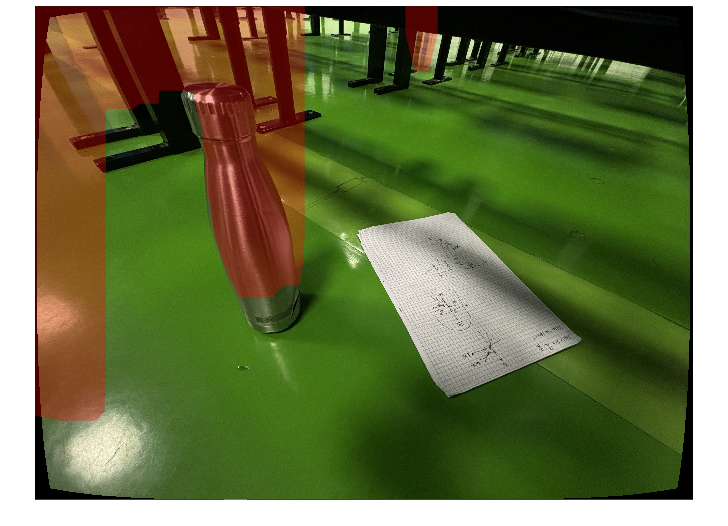

pause(0.5); % Doesn't plot in the right place without this.

figure("Name", "Result");
imshow(images{2});
hold on;

% Area plot.
x = 1:size(diffTh, 2);
y1 = firstWhite;
y2 = zeros(size(y1));
area(x, [y1; y2]', 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.3);